# **simpleUSBCameraTutorial.mlx is a template for future Fun-Robo code**

This is a simple color object tracking USB Camera Tutorial for your robots.

*This example shows how to use the snapshot function to acquire live images from USB webcams. To use it, you need  to first load:*

***MATLAB Support Package for USB Webcams**** which provides the abilitiy to bring live images from any USB video class (UVC) compliant webcam into MATLAB.*

*Available USB webcam functions:*

- *webcamlist        - List of webcams connected to your system*

- *webcam            - Connection to a webcam*

- *preview             - Preview live video data from webcam*

- *snapshot           - Acquire single image fram from a webcam*

- *closePreview    - Close webcam preview window*

Esme Abbot, Izzie Abilheira, Maya Sivanandan - 03/29/2021 - Rev. 0

clc     % clear command window
clear   % clear MATLAB workspace
imaqreset   % clear all image objects from memory

### Set Up Robot Control System

This code runs once

%Identifying Available Webcams, the webcamlist function provides a cell
%array of all webcams on the current system that MATLAB can access.
%webcam(2) is hopefully {'Microsoft LifeCam Cinema'}, if not change code
%below

camList = webcamlist

camList = 2×1 cell array
    {'Integrated Webcam'      }
    {'USB2.0 HD UVC AF Camera'}



%Set up connection to the USB Webcam, print its properties
robotCam = webcam(2)

robotCam =   webcam with properties:

                     Name: 'USB2.0 HD UVC AF Camera'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'  '1280x720'  '1280x800'}
               Resolution: '640x480'
                     Tilt: 0
                      Pan: 0
                Sharpness: 25
             ExposureMode: 'auto'
                     Gain: 0
                FocusMode: 'auto'
                    Focus: 0
                 Contrast: 128
                     Zoom: 0
                 Exposure: -6
    BacklightCompensation: 1
               Saturation: 128
                      Hue: 0
                    Gamma: 100
         WhiteBalanceMode: 'auto'
             WhiteBalance: 4600
               Brightness: 0


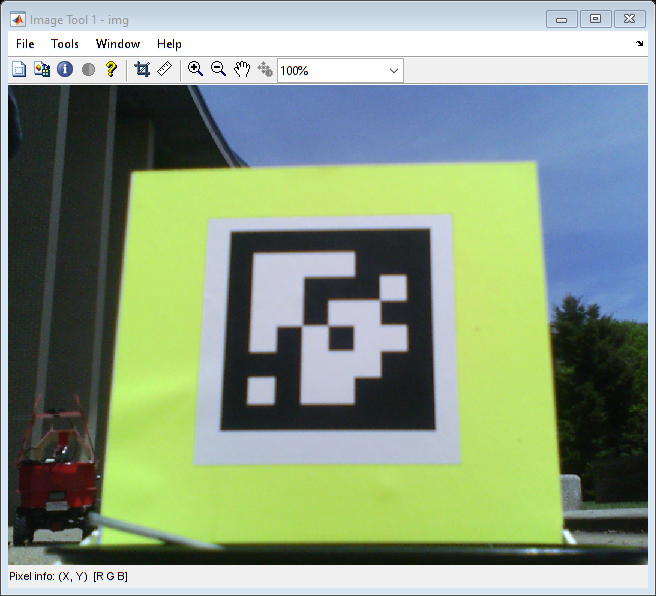


%Fix auto exposure problem set it to manual, set exposureto work in lab
%lighting set whitebalance to manual too. Auto exposure and white balance
%drive computer vision algorithims crazy by constantly changing
SETUPUSBCAMERA(robotCam);

% preview video stream
preview(robotCam);

gCamTest = input('move hand in front of camera, type G, then hit ENTER', 's');
clc;

% close Preview window
closePreview(robotCam);

% acquire a frame
img = snapshot(robotCam);

% display the frame in the imtool window
imtool(img);

gCamTest = input('experiment with tool, type G, then hit ENTER', 's');

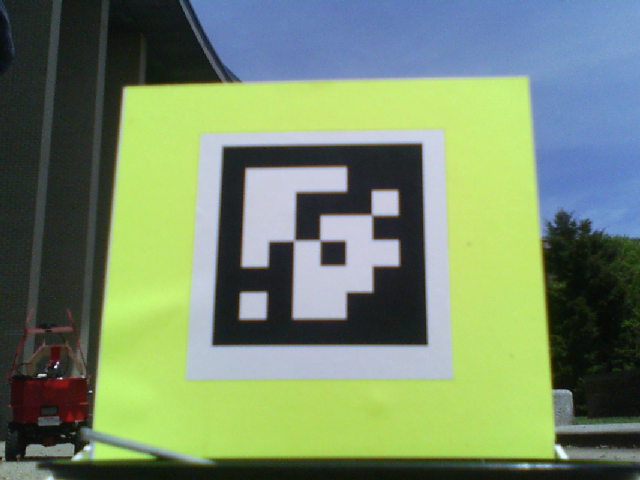

clc;

camWindow = figure('name', 'Robot USB Camera', 'NumberTitle', 'off', 'visible', 'on');
figure(camWindow)
imshow(img, 'Border', 'tight')


% Configure test loop to collect n data points
nTests = input(['Enter small number of camera tests, ' 'followed by enter: ']);
clc

r = rateControl(0.1);
reset(r);

### Run Robot Control Loop

This code runs repeatedly

nameTag = 't1'

controlFlag = 2

nameTag = 't2'

controlFlag = 3

nameTag = 't3'

controlFlag = 4

nameTag = 't4'

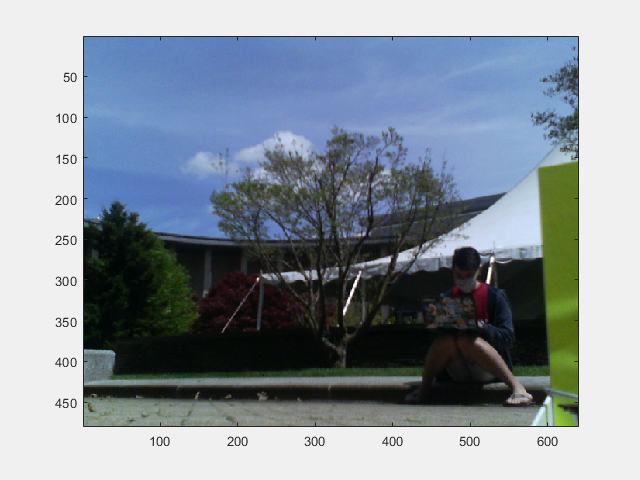

controlFlag = 5

controlFlag = 1;
% create a loop control
while (controlFlag < nTests+1)  % loop until ntests data captured
    
    robotIMG = SENSE(robotCam); % capture a USB camera image
    figure(camWindow)           % go to camWindow to show new image with imshow
    image(robotIMG)             % show image in camWindow figure
    
    THINK();                    % compute what robot should do next
    ACT();                      % command robot actuators
    
    nameTag = input('Enter image file name, then hit ENTER:','s')
    filename = [nameTag '.jpg'];
    imwrite(robotIMG, filename);
    
    % pause to allow you to move objects
    camtest = input('move object to new position, type G, then hit ENTER','s');
    clc;
    
    waitfor(r);                 % wait for loop cycle to complete
    controlFlag = controlFlag + 1 % increment loop
end

### Robot Control Functions

Local functions are stored here

function [] = SETUPUSBCAMERA(robotCam)
    % SETUPUSBCAMERA creates and configures a Webcam to be a simple robot
    % vision system. It requires a standard webcam attached to your
    % computer and takes webcam object name as sole input. You need to set
    % your cameras unique parameters to optimize pictures.
    % 2021 Rev 0
    
    % Fix auto exposure set it to manual, set whitebalance to manual to
    %robotCam.WhiteBalanceMode = 'manual';
    %robotCam.ExposureMode = 'manual';
    
    % OR experimentally determine best exposure setting for lab
     robotCam.Exposure = -13;
     robotCam.WhiteBalanceMode = 'manual';
    
    robotCam.Brightness = 10;
end


#### Sense Functions

function [robotImage] = SENSE(robotCam)
    % This function acquires a single image from the USBCamera testCam and
    % displays it in a stand alone figure
    
    robotImage = snapshot(robotCam);
    
end

#### Think Functions

function THINK()
    % no thoughts, head empty :)
end

#### Act Functions

function ACT()
    % no do, knees broken :(
end